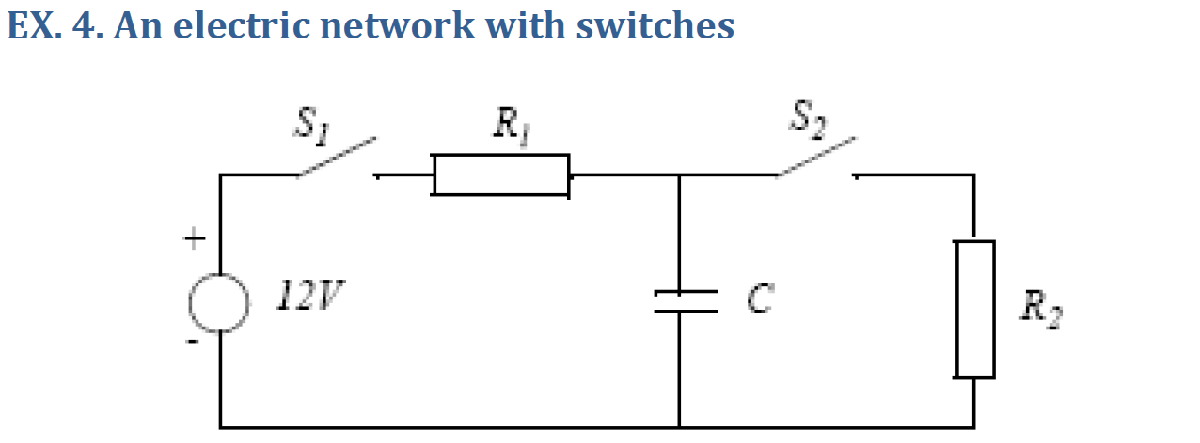

### Basic parameters

The basic parameters of the system are given in the problem description.


$$R = R_1 = R_2

$$


V_in = 12; % [V]
R_1 = 200; % [Ohm]
R_2 = 200; % [Ohm]
R = R_1;
C = 10 * 10^-6; % [F] (10 uF)

### Transfer function models

Our task was to derive transfer function models for the system in the following two cases:

    1. When S1 is closed and S2 open

    2. When S1 and S2 are closed after case 1 was active for 0.2 seconds. 

On paper we concluded that the capacitor will be fully charged at this point. This will be supported by the subsequent diagrams.


$$G_1(s) = \frac{1}{RCs +1}
$$



$$G_2(s) = \frac{1}{RCs + 2}
$$


However the transfer function for case 2 assumes zero initial conditions, which we know is not the case.

The formula for the voltage over the capacitor is:


$$V_C = V_i  \frac{1}{RCs +2} + \frac{V_0RC}{CRs + 2}$$


Where the term first term is G_2 and the second term is the non-zero initial conditial term. 

% Derived transfer function model of case 1.

s = tf('s');
G1 = 1/(R*C*s + 1);

G2 = 1/(R*C*s + 2);

### Step response of G1

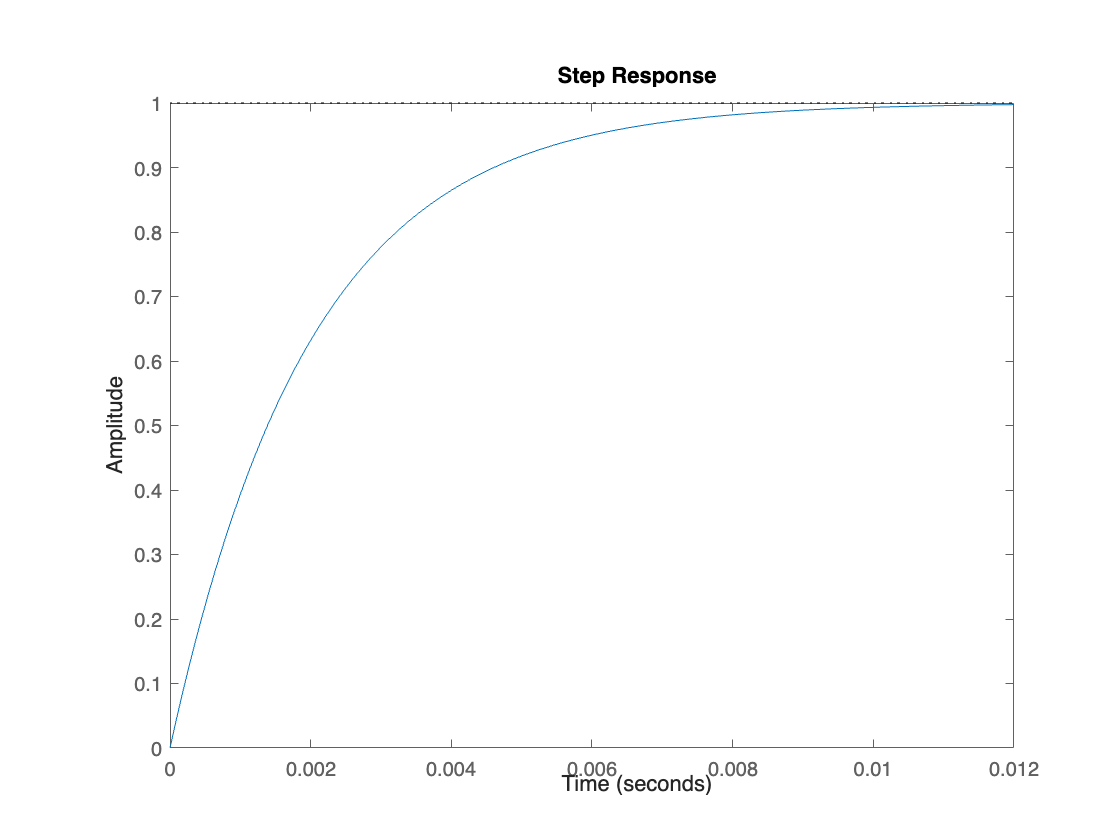

figure;
sp1 = stepplot(G1);

### Step response from force to velocity at node 2

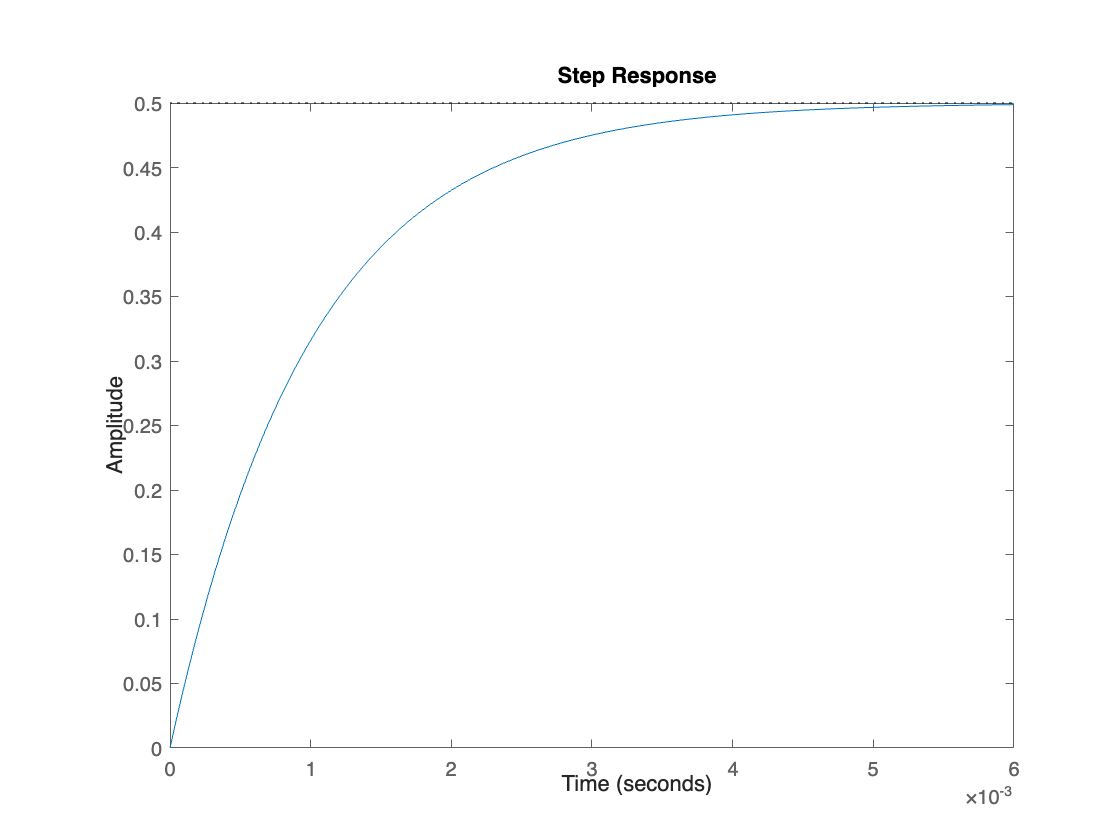

figure;
sp2 = stepplot(G2);

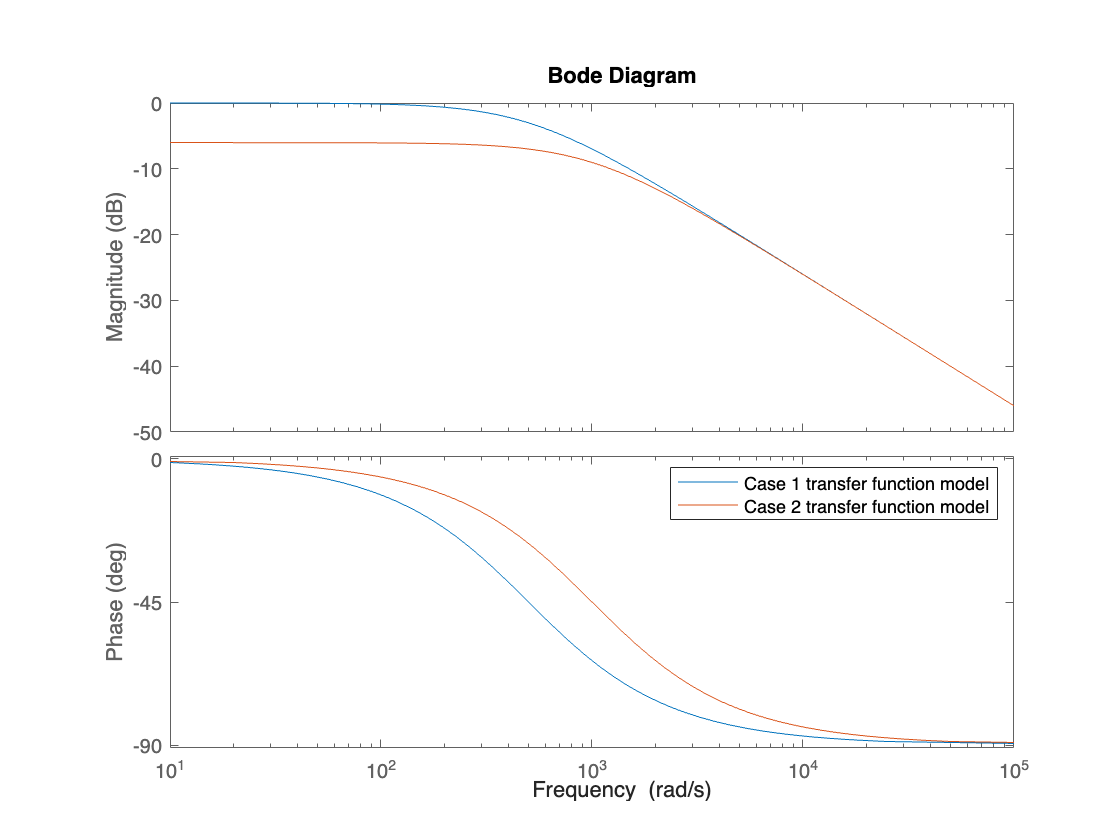

figure;
bode(G1,G2)
legend("Case 1 transfer function model", "Case 2 transfer function model")

### Simulink and simscape models

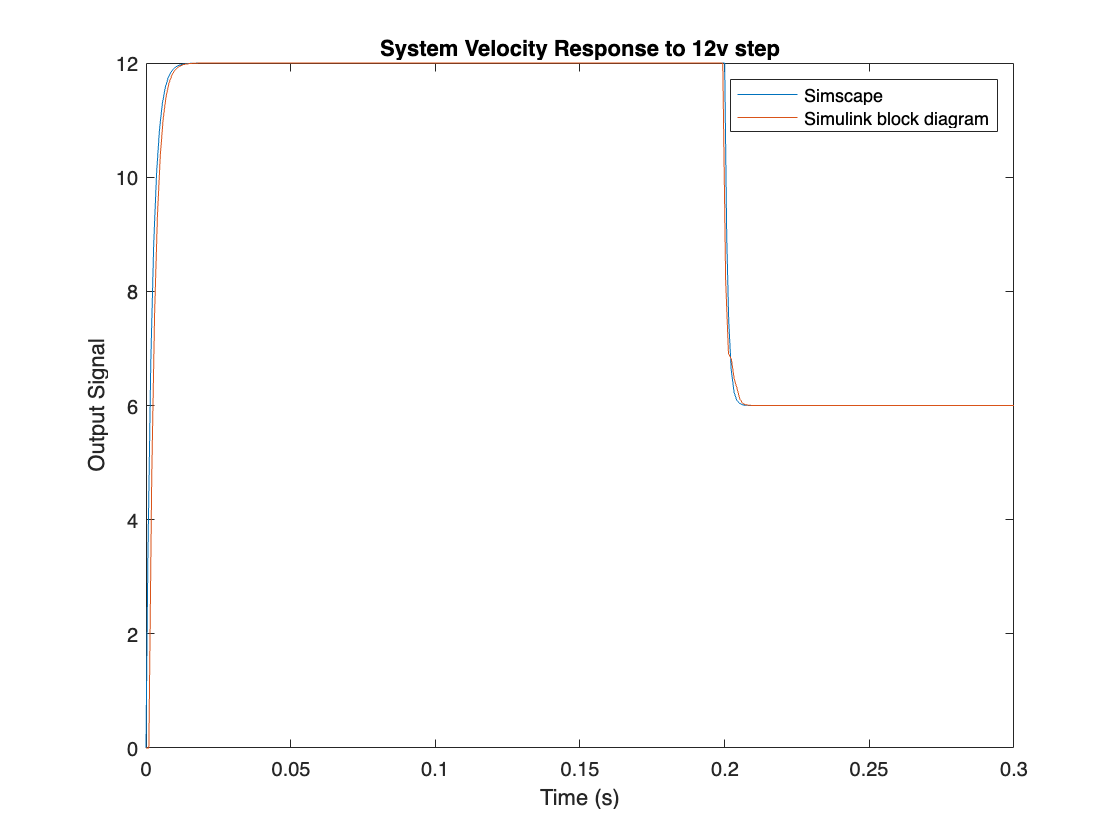

model_name = 'Part1_new2'; 
load_system(model_name);

runningtime = num2str(0.3);

set_param(model_name, 'StopTime', runningtime); 

simOut = sim(model_name);


sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('Voltage_out').Values.Data; 


model_name = 'excercise1_bd_ex4'; 
load_system(model_name);


set_param(model_name, 'StopTime', runningtime); 
set_param(model_name, 'Solver', 'ode45');
set_param(model_name, 'MaxStep', '0.001');

simOut = sim(model_name);


sim_time22 = simOut.tout;
output_signal22 = simOut.logsout.getElement('Ucap').Values.Data; 


figure;
plot(sim_time22, output_signal22);
title(['System Velocity Response to 12v step']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on

runningtimeint = str2num(runningtime);
tvec = linspace(0,runningtimeint,length(output_signal12));

plot(tvec, output_signal12)
legend("Simscape", "Simulink block diagram")
hold off

In the system response in Simscape and Simulink block diagram we can see that both the systems behave the same. In the block diagram model the two different models with and without the switch were connected with a sum block to form the correct relationship. 

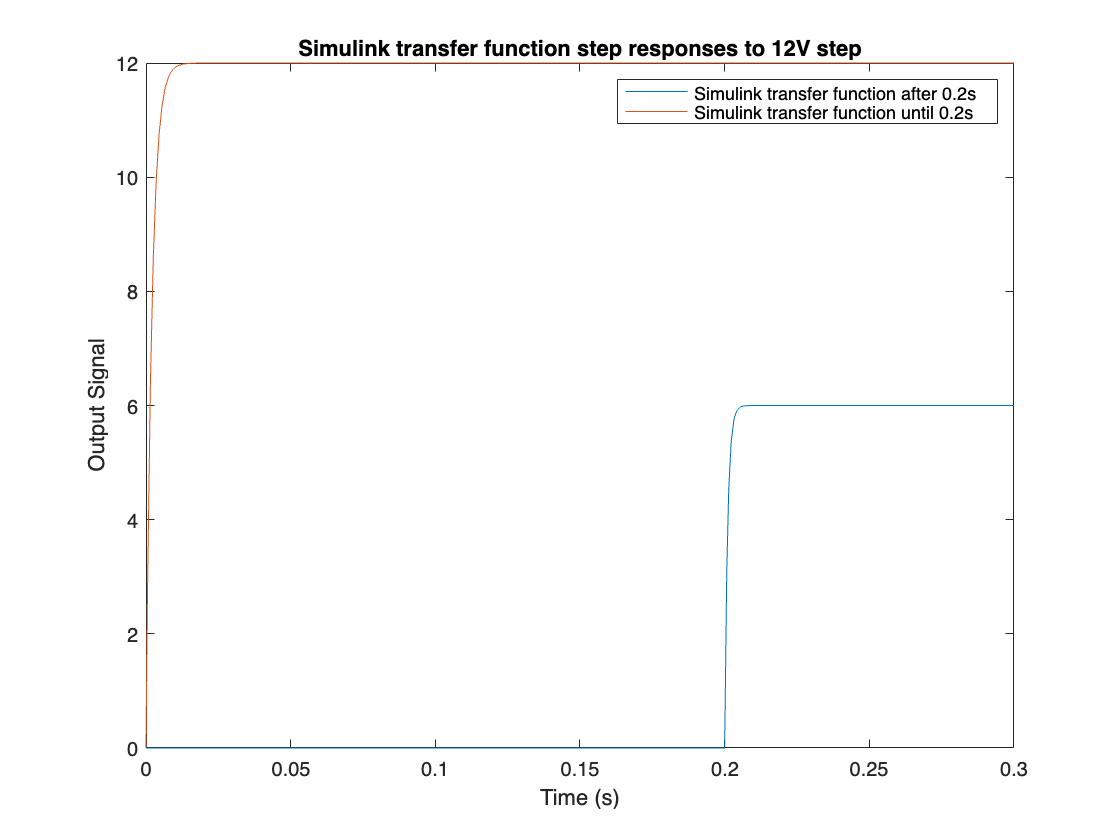

model_name = 'excercise1_tf_ex4'; 
load_system(model_name);

runningtime = num2str(0.3);

set_param(model_name, 'StopTime', runningtime); 
set_param(model_name, 'Solver', 'ode45');
set_param(model_name, 'MaxStep', '0.001');

simOut = sim(model_name);


sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('U1').Values.Data; 


model_name = 'excercise1_tf_ex4'; 
load_system(model_name);


set_param(model_name, 'StopTime', runningtime);
set_param(model_name, 'Solver', 'ode45');
set_param(model_name, 'MaxStep', '0.001');

simOut = sim(model_name);


sim_time22 = simOut.tout;
output_signal22 = simOut.logsout.getElement('U2').Values.Data; 


figure;
plot(sim_time22, output_signal22);
title(['Simulink transfer function step responses to 12V step']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on

plot(sim_time12, output_signal12)
legend("Simulink transfer function after 0.2s" ,"Simulink transfer function until 0.2s")
hold off

Here we can see the step responses in the simulink transfer function simulations. The simulation for when both switches are closed shows an opposite behavior to what is expected (goes from 0v to 6v instead of from 12v to 6v). This is because the transfer function blocks in simulink do not have initial value parameters for the input voltage. This could however most likely be handled with the same construction as for the block diagram in the previous graph. 